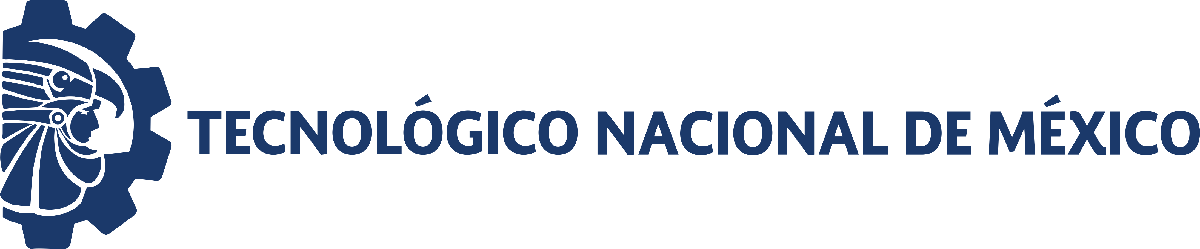                                 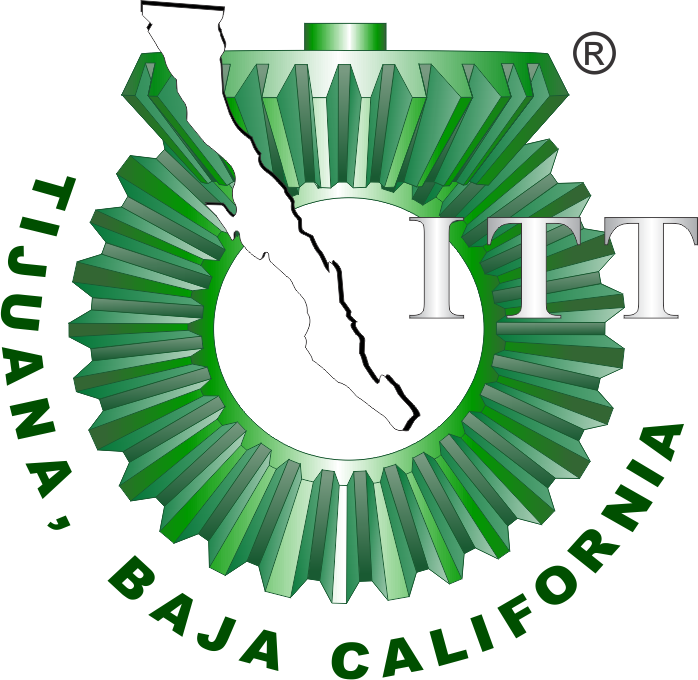

# Práctica dos: Sistema musculoesquelético

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

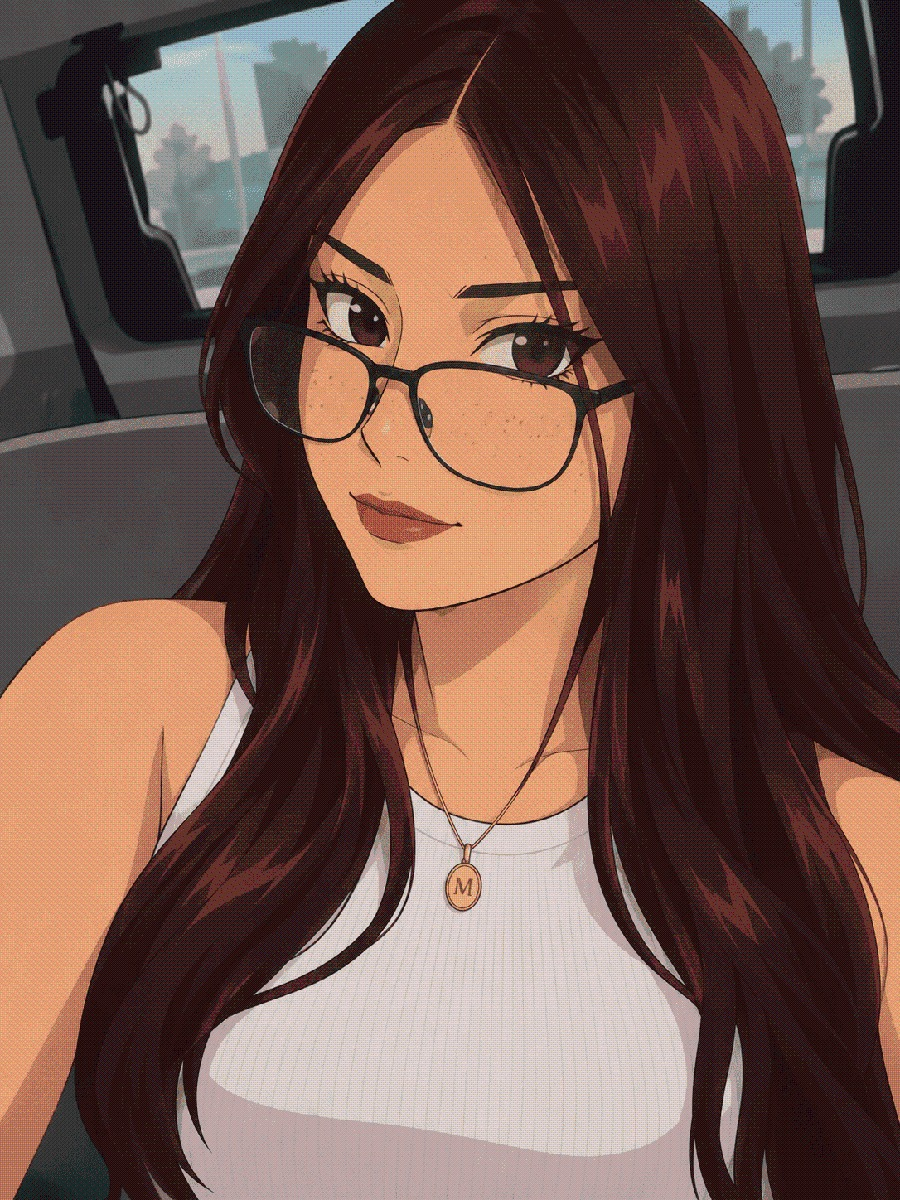

Nombre del alumno: Mildred Angel Torales

Número de control: 23212731

Correo institucional: l23212731**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Practica3_MSF1_MAT')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x= sim('Practica3_MSF1_MAT',parameters);

## Modelo de EDOs

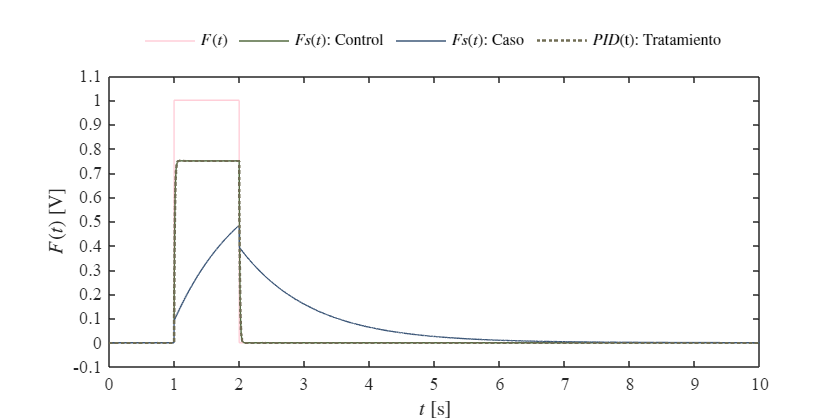

dt = 1e-3;
t = (0:dt:10)';
F = zeros(length(t),1); F(1/dt:2/dt) = 1;
PID = interp1(x.t,x.PID, t, 'previous');

par_control = [0.25,10e-6,100e-6,100];
par_caso = [0.25,10e-6,100e-6,10e3];

Fs_control = musculoesqueletico(par_control,F,t);
Fs_caso = musculoesqueletico(par_caso,F,t);

plotsignals(t,F,Fs_control,Fs_caso,PID, 'EDOsys')





function Fs = musculoesqueletico(par,F,t)
    alpha = par(1); Cs = par(2); Cp = par(3); R = par(4); dt = t(2);
    n = round(t(end)/dt);
    x = zeros(length(t),1); x(1) = 0;
    Fs = zeros(length(t),1); Fs(1) = 0;
    for i = 1:n
        x(i+1) = x(i) + ((F(i)-x(i))/(R*(Cp+Cs)))*dt; %EDO
        Fs(i+1) = Cs*F(i)/(Cp+Cs) + (1 - alpha - Cs/(Cp+Cs))*x(i); %función 
    end

end


## Caso

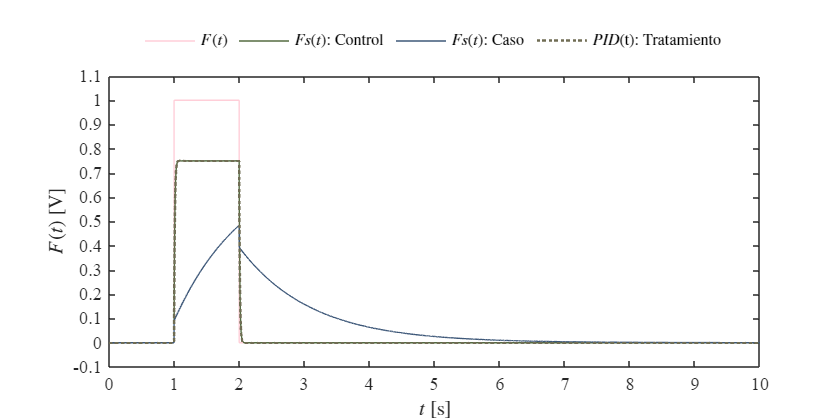

plotsignals(x.t,x.F,x.Fsx,x.Fsy,x.PID,'Caso')

## Funcion: Respuesta de simulacion

function plotsignals(t,F,Fs1,Fs2,pid,name)
    set (figure(),'color','w')
    set (gcf,'units','inches','position',[1,1,7,3.5])
    set (gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
  
 
    clr1 = [255, 206, 216]/255;
    clr2 = [84, 107, 65]/255;
    clr3 = [62, 88, 121]/255;
    clr4 = [112, 109, 84]/255;

    plot (t,F,'-','LineWidth',0.25,'Color',clr1)
    plot (t,Fs1,'-','LineWidth',0.25,'Color',clr2)
    plot (t,Fs2,'-','LineWidth',0.25,'Color',clr3)
    plot (t,pid,':','LineWidth',1.5,'Color',clr4)
     
    L = legend('$F(t)$','$Fs(t)$: Control','$Fs(t)$: Caso','$PID$(t): Tratamiento');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal','box','off')    
    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$F(t)$ [V]','interpreter','latex')

    xlim([0 10]); xticks(0:1:15)
    ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)

    exportgraphics(gcf,['matlab_',name,'.pdf'],'contenttype','vector')
    exportgraphics(gcf,'sistemaME.png','Resolution',600);
    print('sistemaME','-dsvg');
    print('sistemaME','-depsc');
end